# ECSE 343: Assignment 1

Theodore Janson

260868223 

**Question 1 **

a) The machine epsilon 𝜖𝑚 can also be thought of as the difference between 1 and the next higher number that can be stored using floating point representation on a computer. The matlab function eps()provides this value. Note that the distance between two floating point numbers is not constant. Use the above function to compute the value of 𝜖 for different values of n. Use n = 1,2,3,4,5, 7, 8, 15, 200, 1022, and 1023, 1.3e6. Explain the results you obtain.

for n = [1,2,3,4,5,7,8,15,200,1022,1023,1.3e6]
    fprintf("The absolute error for n = "+n+" is "+ep(n)+'\n')
end

The absolute error for n = 1 is 2.2204e-16
The absolute error for n = 2 is 4.4409e-16
The absolute error for n = 3 is 4.4409e-16
The absolute error for n = 4 is 8.8818e-16
The absolute error for n = 5 is 8.8818e-16
The absolute error for n = 7 is 8.8818e-16
The absolute error for n = 8 is 1.7764e-15
The absolute error for n = 15 is 1.7764e-15
The absolute error for n = 200 is 2.8422e-14
The absolute error for n = 1022 is 1.1369e-13
The absolute error for n = 1023 is 1.1369e-13
The absolute error for n = 1300000 is 2.3283e-10


b) The function provided in part a gives an estimate of the absolute roundoff error when storing a Real number as a floating-point number 𝑛 (the round-off error is 𝜖/2). Write a similar function rel_ep(n)that computes the relative error. Call the function for the same values of 𝑛 used in part a. Explain the difference in the results. 

for n = [1,2,3,4,5,7,8,15,200,1022,1023,1.3e6]
    fprintf("The relative error for n = "+n+" is "+rel_ep(n)+'\n')
end

The relative error for n = 1 is 4.4409e-16
The relative error for n = 2 is 4.4409e-16
The relative error for n = 3 is 2.9606e-16
The relative error for n = 4 is 4.4409e-16
The relative error for n = 5 is 3.5527e-16
The relative error for n = 7 is 2.5377e-16
The relative error for n = 8 is 4.4409e-16
The relative error for n = 15 is 2.3685e-16
The relative error for n = 200 is 2.8422e-16
The relative error for n = 1022 is 2.2248e-16
The relative error for n = 1023 is 2.2226e-16
The relative error for n = 1300000 is 3.582e-16


c) Using your knowledge of the floating-point representation find and evaluate an expression that computes epsilon at 1 for a single precision (32bit) floating point number (compare with the matlab function eps(‘single’).

value = eps('single')

ans = single
1.1921e-07

ans = 1.1921e-07

**Question 2 **

The derivative of a function, f(x), can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function, about 𝑥0. Rearranging terms to solve for 𝑓 ′ (𝑥0 ) and ignoring the higher-order terms, we obtain the first order approximation of derivative. 

a) Implement the function using the structure given below to compute the derivative of sin(x). Use this function to compute the derivative of the sin(x) at 𝑥0 = 𝜋 / 4 . 

der = dydx(pi/4)

der = 0.7071

b) In this part, we will implement the code to compute the derivative of sin(x) at 𝑥0 = 𝜋 / 4 							using the divided differences formula shown in equation (2.2). What is the expression for truncation error?Use the provided script (*dydx_approx.mlx)*, implement the divided difference formula and the truncation error. Include plot of the absolute error and the truncation error vs h in your report. Explain the why the error is smooth of the error for large values of h while it is erratic for small values of h. 									

h = logspace(-20,0,100);

x0 = pi/4;
derivative= dydx(x0);

dydx_approx = (sin(x0+h)-sin(x0))./ h           %IMPLEMENT equation (2.2) here 

dydx_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.6107    1.0116    1.2706    0.7980    0.7517    0.7869    0.6918    0.7448    0.7407    0.7345    0.7073    0.7146    0.7095    0.7084    0.7080    0.7075    0.7076    0.7074    0.7070    0.7071    0.7073    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071


abserr = abs(derivative - dydx_approx);
truncation_error = sin(x0) .* h / 2                                

truncation_error =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


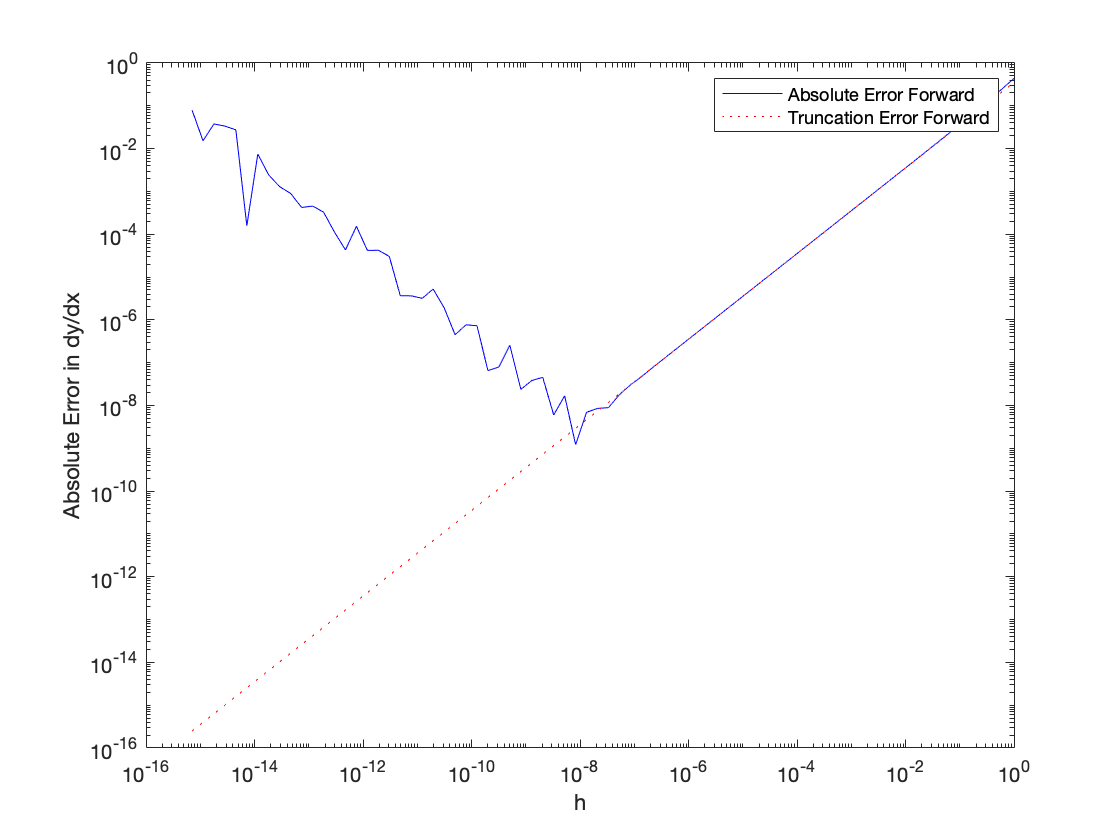


clf
figure(1)
loglog(h(25:100),abserr(25:100),'b')
hold on
figure(1)
loglog(h(25:100),truncation_error(25:100),'r:')

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error Forward','Truncation Error Forward')

c)  In part (b), at which value of h did you obtain the minimum error. Justify your answer and show all the computations. 	

[min_err,i] = min(abserr)

min_err = 1.2208e-09

i = 60

min_h = h(i)

min_h = 8.3022e-09

d) Implement the code to compute the derivative of sin(x) at 𝑥0 = 𝜋 using the divided differences formula shown in equation (2.4) What is the expression for truncation error? Show the plot of the absolute error and the truncation error vs h. 						

h = logspace(-20,0,100);
x0 = pi/4;
derivative= dydx(x0);

dydx_central_approx = (sin(x0 + h) - sin(x0 - h)) ./ (2*h)                            

dydx_central_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8054    0.5058    0.9530    0.7980    0.6264    0.7082    0.6918    0.7138    0.7212    0.7222    0.7073    0.7097    0.7065    0.7084    0.7068    0.7075    0.7071    0.7071    0.7070    0.7070    0.7072    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071


abserr_cen = abs(derivative - dydx_central_approx);

truncation_error_cen = cos(x0).*h.^2/ (factorial(3))

truncation_error_cen =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


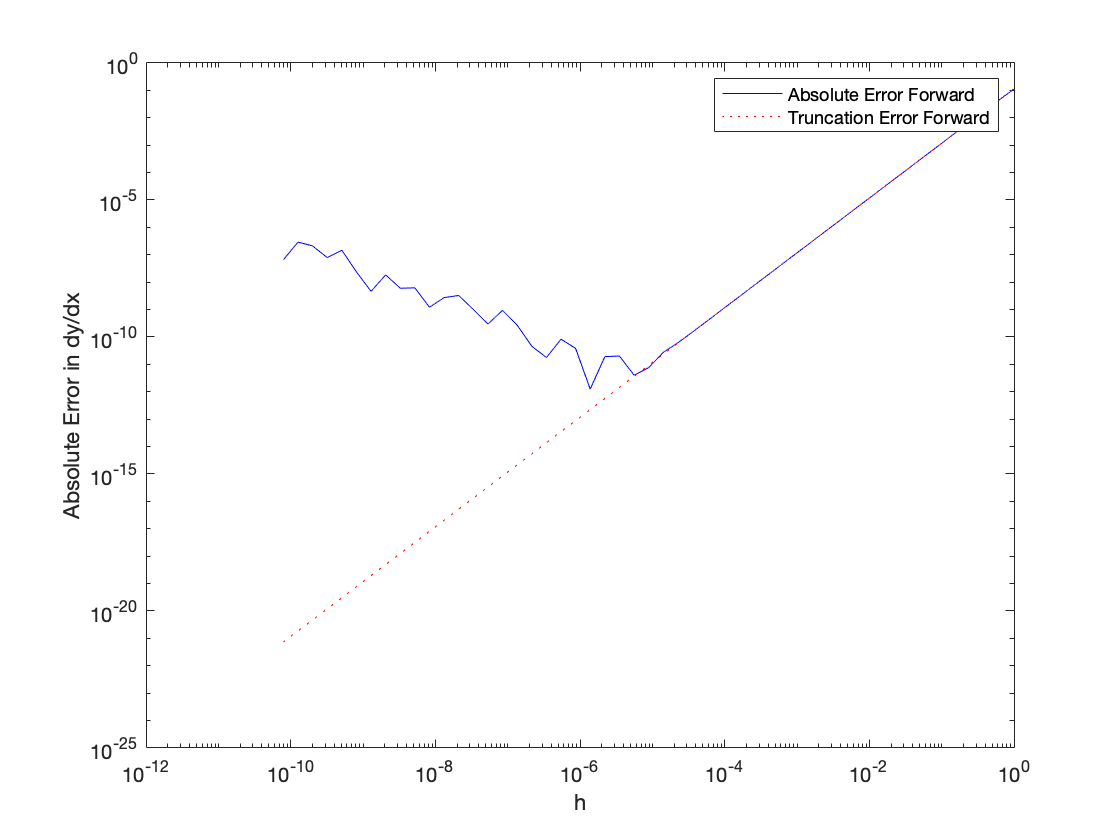


clf
figure(1)
loglog(h(50:100),abserr_cen(50:100),'b')
hold on
figure(1)
loglog(h(50:100),truncation_error_cen(50:100),'r:')

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error Forward','Truncation Error Forward')

e) Which difference formula gives a smaller absolute error? Explain. 							

[min_err,i] = min(abserr_cen)

min_err = 1.2582e-12

i = 71

min_h = h(i)

min_h = 1.3849e-06

**Question 3 **

a) Write a MATLAB function name *LU_decomposition.m *to compute the LU factorization using Gaussian Elimination. Use the stencil of function provided below to implement your code. 

% A = [2 1 -2 ; 4 5 -3 ; 6 9 -2];
% [L,U] = LU_decompositon(A);


 b) Write a MATLAB function named *LU_rowpivot.m *to compute the Gaussian Elimination based LU factorization **using the partial pivoting **(row pivoting). The function should take matrix as the input and should output L, U and P matrices as described below. 

A = [2 3 2 ; 1 2 3; 4 1 2];
[L,U,P] = LU_rowpivot(A);

c) Write the MATLAB functions named *forward_sub.m *and *backward_sub.m *to compute the forward and backward substitutions, respectively. 

d) Use the LU decomposition implemented in part (a) along with forward and backward substitution functions written in part (c) to solve the following system of equations. List the values of vector X obtained. 

A = [1e-16 2 5 5 ; 0.2 1.6 7.4 5 ; 0.5 4 8.5 5 ; 0.5002 8 11 97];
b = [400 ; 5; 18; 95];

[L,U] = LU_decompositon(A);

check = L*U

check =     0.0000    2.0000    5.0000    5.0000
    0.2000    1.5000    8.0000    6.0000
    0.5000    4.0000    8.0000    4.0000
    0.5002    8.0000   12.0000   96.0000



y = forward_sub(L, b);
x = backward_sub(U, y)

x = 	1.0e+18 *

    4.0000
    0.0000
    0.0000
   -0.0000


e) Use the LU decomposition with partial pivoting implemented in part (b) along with forward and backward substitution functions written in part (c) to solve the above system of equations. List the values of vector X obtained. 		

A = [1e-16 2 5 5 ; 0.2 1.6 7.4 5 ; 0.5 4 8.5 5 ; 0.5002 8 11 97]

A =     0.0000    2.0000    5.0000    5.0000
    0.2000    1.6000    7.4000    5.0000
    0.5000    4.0000    8.5000    5.0000
    0.5002    8.0000   11.0000   97.0000


[L, U, P] = LU_rowpivot(A);

check1 = P*A

check1 =     0.5002    8.0000   11.0000   97.0000
    0.5000    4.0000    8.5000    5.0000
    0.2000    1.6000    7.4000    5.0000
    0.0000    2.0000    5.0000    5.0000


check2 = L*U

check2 =     0.5002    8.0000   11.0000   97.0000
    0.5000    4.0000    8.5000    5.0000
    0.2000    1.6000    7.4000    5.0000
    0.0000    2.0000    5.0000    5.0000



y = forward_sub(L, P*b);
x = backward_sub(U, y)

x =   189.9240
  206.5590
    5.6708
   -8.2944


**Functions: **

Question 1.a)

function eplison = ep(n)
    eplison = double(1);
    r = eplison/2;
    while (n+eplison) ~= n
        eplison = eplison/2;
        r = eplison/2;
    end
    eplison= eplison*2;
end

Question 1.b)


function round_error = rel_ep(n)
    round_error = ep(n) * 2 / n;
end

Question 2. a)


function der = dydx(x0)
    der = cos(x0);
end

Question 3.a)

function [L, U] = LU_decompositon(A) 
  dim = size(A); n = dim(1,1); %get dimension of A, and number of rows
  L = zeros(dim);  %Initialize L to identiy as L = I * ∏(Einv), where Einv are in ascending order of computation
  U = A;         %Initialize U to A as U = ∏E * A, where E are in descending order of computation
  
  for p = 1:n %iterate over each pivot (each element in the diagonal)
    pivot = U(p,p);
    for row = (p+1):n %for each row below the pivot's row (and in the pivots column)
        l = - (U(row,p) / pivot);     %compute l = first non zero element in row to reduce / pivot
        E = eye(dim);  E_inv = zeros(dim);    
        E(row,p) = l; E_inv(row,p) = -l;   %construct Elimination and inverse elimination matrices using l
        L = L + E_inv;                  % Update L and U
        U = E * U; 
    end
  end
  L = L + eye(dim); 
end

Question 3.b)

function [L, U, P] = LU_rowpivot(A) %similar to part 3.a)

  dim = size(A); n = dim(1,1); 
  L = zeros(dim); %Initialize L matrix to zeros so we can do row swaps without changing the 1s diagonal
  U = A;
  P = eye(dim); %Permutation matrix
  
  for p = 1:n-1
    b = zeros(n,1); 
    b(p:n) = U(p:n,p); %slicing the part of the column below the diagonal
                      %put into zero vector to retain indices of original  array        
    [m,i] = max(abs(b));%get the arg absolute max 

    U([p i],:) = U([i p],:);
    P([p i],:) = P([i p],:); %Swap the pivot's row with the largest element's row
    L([p i],:) = L([i p],:);   
    pivot = U(p,p);
    for row = (p+1):n 
       l = - (U(row,p) / pivot)   ;  
       E = eye(dim); E_inv = zeros(dim);   
       E(row,p) = l; E_inv(row,p) = -l;
       L = L + E_inv ; %Update L such that it only contains the row reduction coefficients 
       U = E * U;
    end
  end
  L = L + eye(dim); % Add the idendity to L
end

Question 3.c)

function y = forward_sub(L, b)
    n = size(b); %dimension
    y = zeros(n); 
    for i = 1:n  %iterate over each row
        y(i) = b(i); %initialize y to b
        for j = 1:i-1 %get y from previous y
            if i ~= 0  %except if first y
              y(i) =  y(i) - y(j)*L(i,j);
            end
        end
        y(i) = y(i) / L(i,i);
    end
end



function X = backward_sub(U, y)
    n = size(y); %dimension
    X = zeros(n); 
    for i = n :-1:1 %iterate over each row backwards
        X(i) = y(i); %initialize X to y
        if i ~= n  %except if last X
            for j = i+1:n %get X from previous X
              X(i) =  X(i) - X(j) * U(i,j);
            end
        end
        X(i) = X(i) / U(i,i);
    end
end